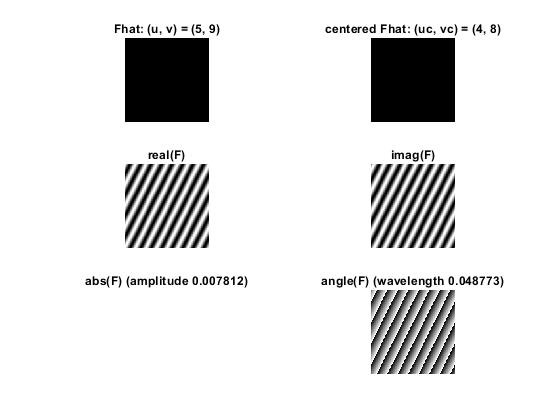

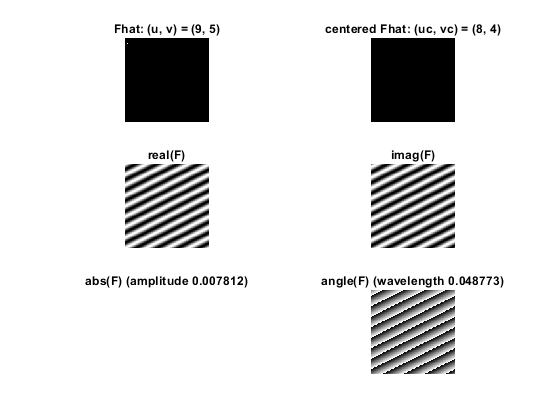

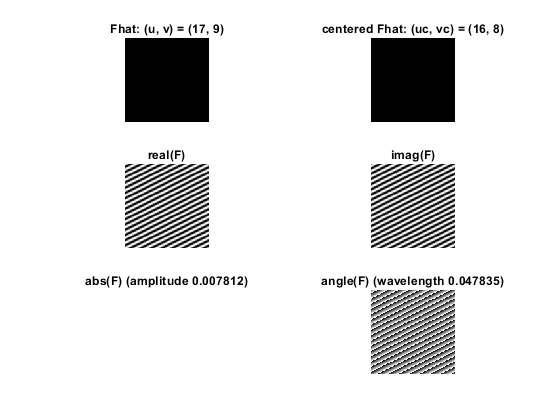

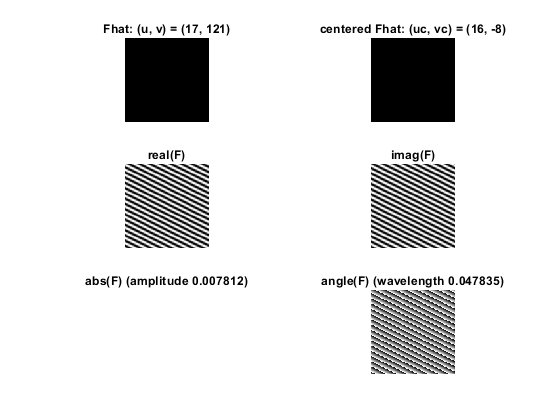

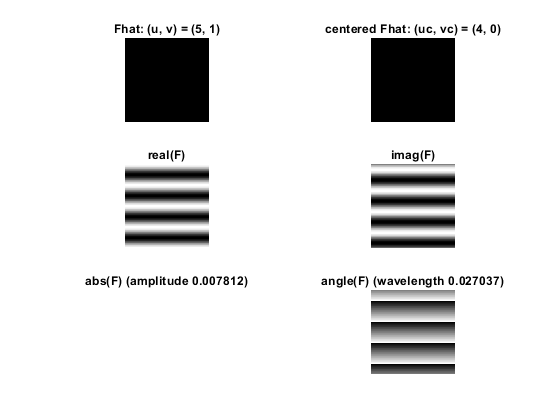

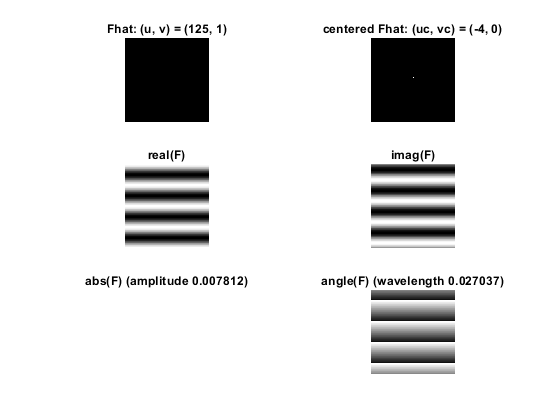

%FFT
u = [5 9 17 17 5 125];
v = [9 5 9 121 1 1];
sz = 128;
for i=1:length(u)
    figure(i)
    fftwave(u(i), v(i),sz);
end

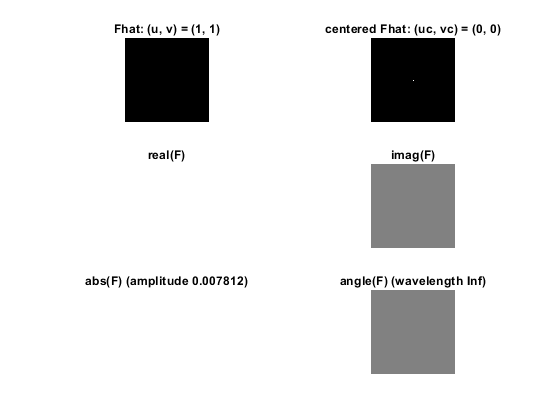

figure(27);
fftwave(1, 1);

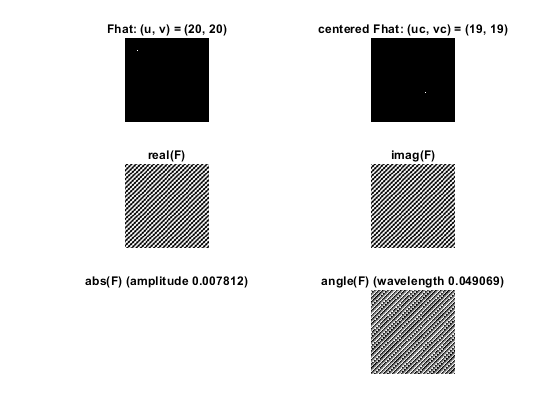

figure(28);
fftwave(20,20);

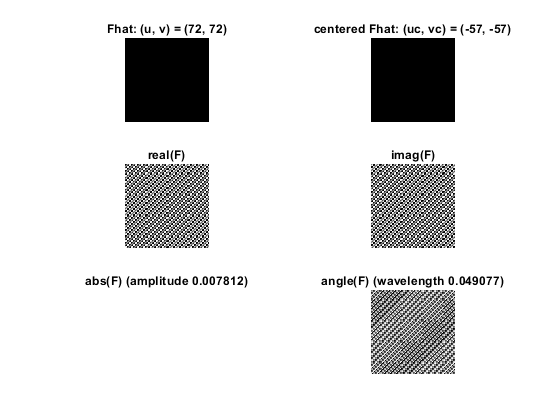

figure(30);
fftwave(72,72);

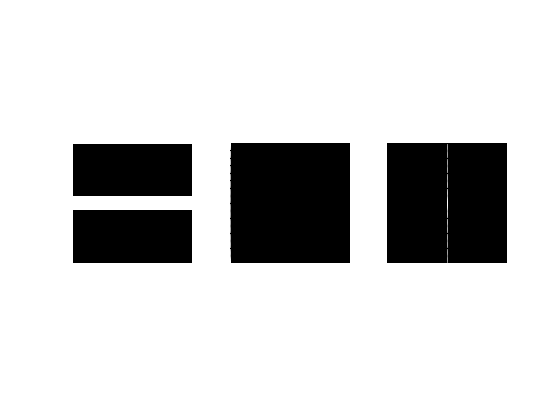

%Linearity
F = [ zeros(56, 128); ones(16, 128); zeros(56, 128)];
G = F';
H = F + 2 * G;

Fhat = fft2(F);
Ghat = fft2(G);
Hhat = fft2(H);
figure(7);
title('Linearity F')
subplot(1, 3, 1);
showgrey(F)
subplot(1, 3, 2);
showgrey(log(1 + abs(Fhat)));
subplot(1, 3, 3);
showgrey(log(1 + abs(fftshift(Fhat))));

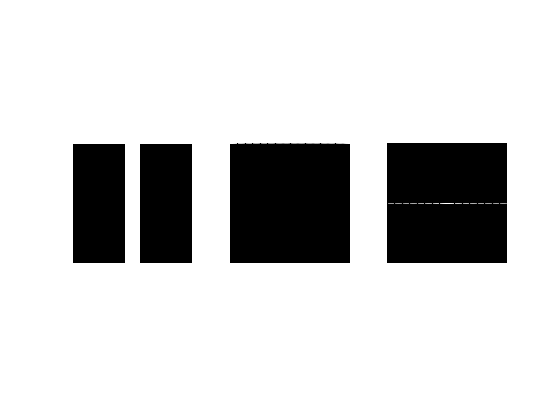

figure(8);
title('Linearity G')
subplot(1, 3, 1);
showgrey(G)
subplot(1, 3, 2);
showgrey(log(1 + abs(Ghat)));
subplot(1, 3, 3);
showgrey(log(1 + abs(fftshift(Ghat))));

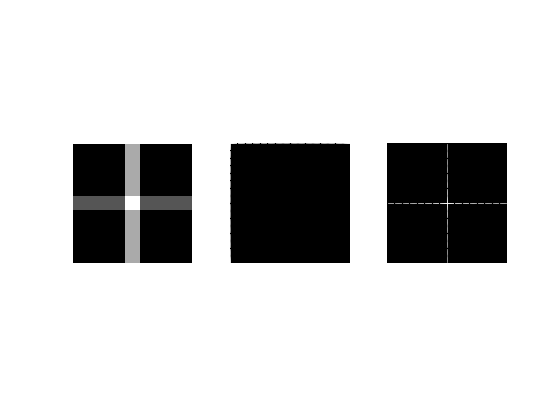

figure(9);
title('Linearity H')
subplot(1, 3, 1);
showgrey(H)
subplot(1, 3, 2);
showgrey(log(1 + abs(Hhat)))
subplot(1, 3, 3);
showgrey(log(1 + abs(fftshift(Hhat))));

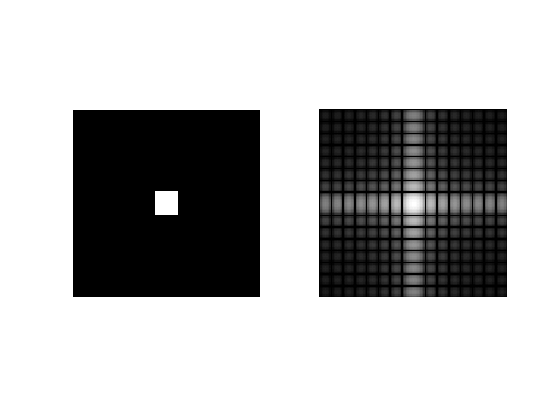

%multiplication
F = [ zeros(56, 128); ones(16, 128); zeros(56, 128)];
G = F';
figure(10);
subplot(1, 2, 1);
showgrey(F .* G);
subplot(1, 2, 2);
showfs(fft2(F .* G));

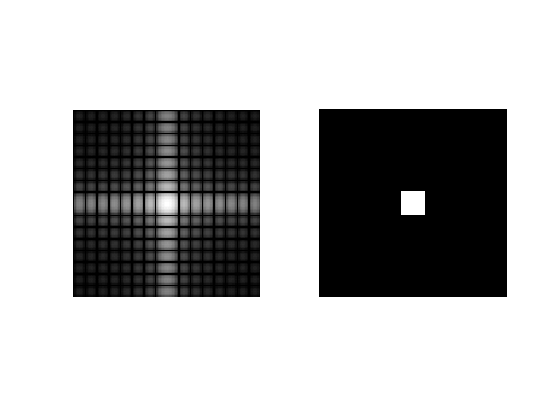

% convolution theorem
% fft2 in matlab does not use the normalization factor 1/MN
Fhat=fft2(F);
Ghat=fft2(G);
FGconv=Fhat*Ghat./(size(F,1)*size(F,2));
figure(11);
subplot(1, 2, 1);
showfs(FGconv);
subplot(1, 2, 2);
showgrey(ifft2(FGconv));

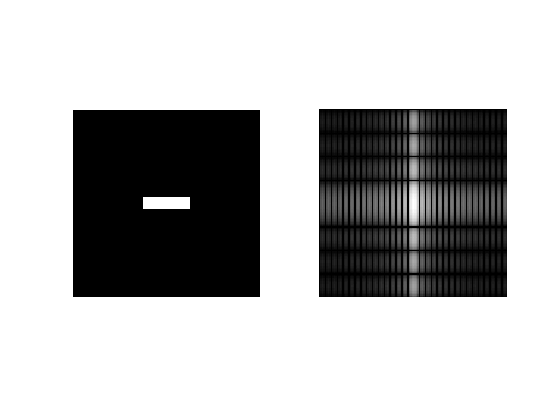

%scaling
F = [zeros(60, 128); ones(8, 128); zeros(60, 128)] .* ...
    [zeros(128, 48) ones(128, 32) zeros(128, 48)];
Fhat=fft2(F);
figure(12);
subplot(1, 2, 1);
showgrey(F);
subplot(1, 2, 2);
showfs(Fhat);

%rotation
F = [zeros(60, 128); ones(8, 128); zeros(60, 128)] .* ...
    [zeros(128, 48) ones(128, 32) zeros(128, 48)];

alphaa = [30 45 60 90];
k = 13

k = 13

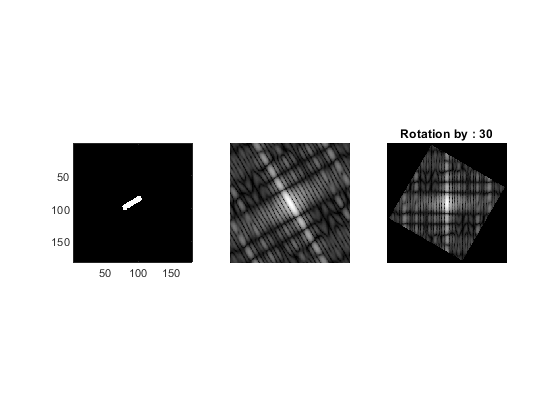

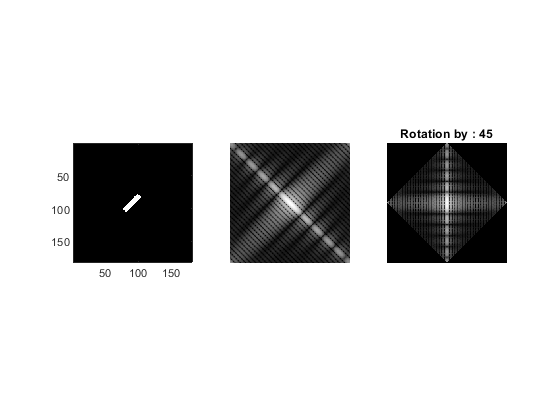

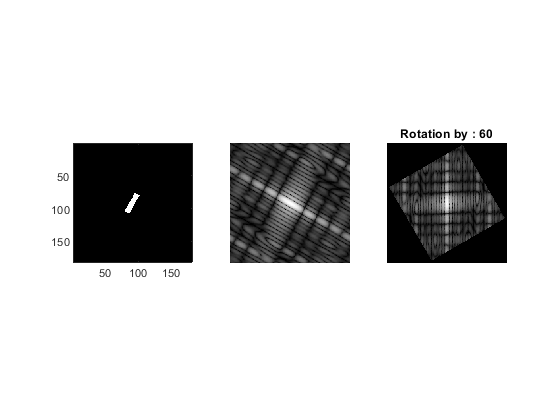

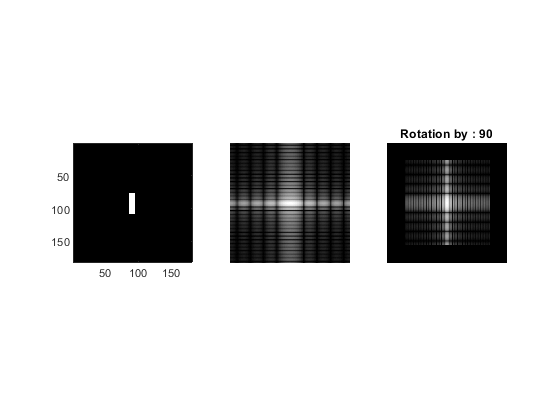

for im=alphaa
    figure(k)
    subplot(1, 3, 1);
    G = rot(F, im);
    showgrey(G)
    axis on
    
    Ghat = fft2(G);
    subplot(1, 3, 2);
    showfs(Ghat);

    Hhat = rot(fftshift(Ghat), -im );
    subplot(1, 3, 3);
    showgrey(log(1 + abs(Hhat)))
    title(['Rotation by : ' num2str(im)])
    k=k+1;
end

%pow2image

img = {phonecalc128 few128 nallo128};
a = 1e-10;
c = 17

c = 17

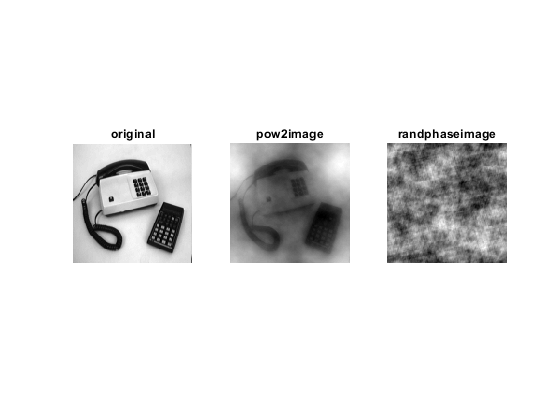

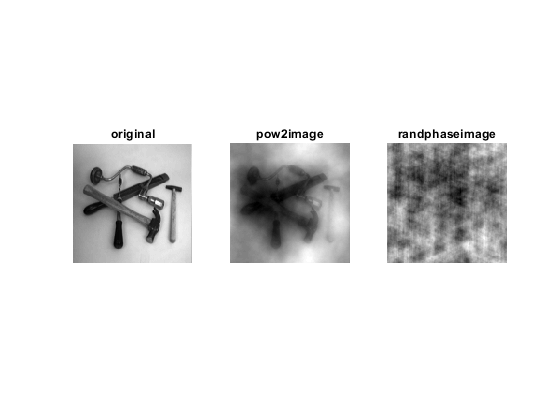

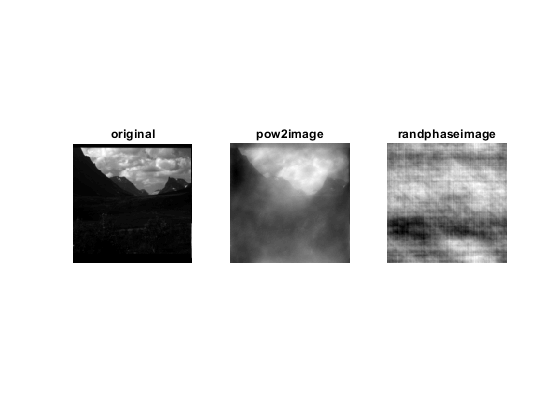

for i=1:length(img)    
    figure(c);
    subplot(1, 3, 1);
    showgrey(img{i})
    title('original')
    subplot(1, 3, 2);
    pow_img = pow2image(img{i}, a);
    showgrey(pow_img)
    title('pow2image')
    subplot(1, 3, 3);
    rand_img = randphaseimage(img{i});
    showgrey(rand_img)
    title('randphaseimage')
    c=c+1;
end

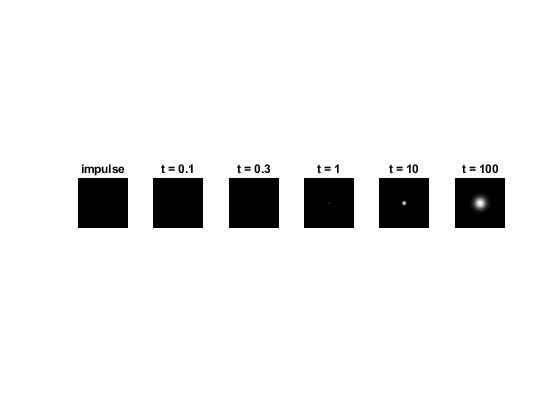

Var =     0.0133    0.0000
    0.0000    0.0133


Test_Var =     0.1000   -0.0000
   -0.0000    0.1000


Var =     0.2811    0.0000
    0.0000    0.2811


Test_Var =     0.3000   -0.0000
   -0.0000    0.3000


Var =     1.0000    0.0000
    0.0000    1.0000


Test_Var =     1.0000    0.0000
    0.0000    1.0000


Var =    10.0000    0.0000
    0.0000   10.0000


Test_Var =    10.0000   -0.0000
   -0.0000   10.0000


Var =   100.0000    0.0000
    0.0000  100.0000


Test_Var =   100.0000   -0.0000
   -0.0000  100.0000


%gaussian filtering using fft
T = [0.1 0.3 1.0 10.0  100.0];
figure(20);
pic = deltafcn(128, 128);
subplot(1, length(T)+1, 1);
showgrey(pic);
title('impulse')
plo = 2;
for t=T
    psf = gaussfft(pic, t);
    subplot(1, length(T)+1, plo)
    showgrey(psf);
    title(['t = ' num2str(t)])
    Var = variance(psf)
    Test_Var = variance(discgaussfft(pic, t))
    plo=plo+1;
end

img = {phonecalc128 few128 nallo128};

T = [1.0 4.0 16.0 64.0 256.0];
pr = 21

pr = 21

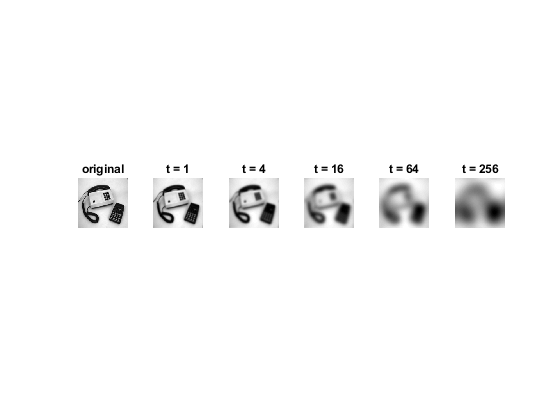

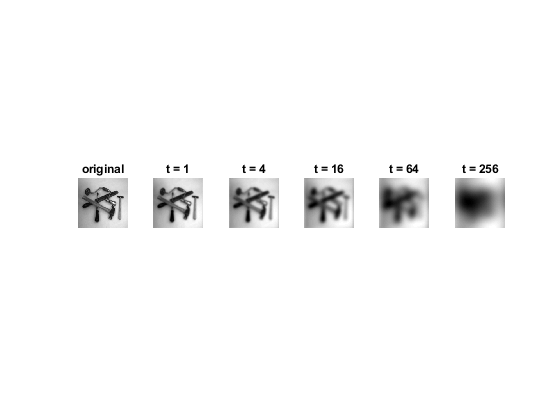

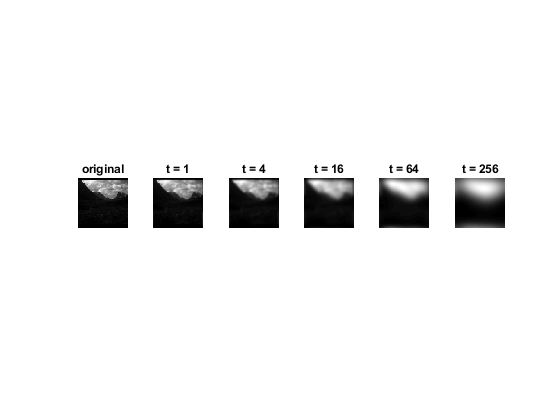

for i=1:length(img)
    figure(pr);
    subplot(1, length(T)+1, 1);
    showgrey(img{i})
    title('original')    
    k = 2;
    for t=T
        psf = gaussfft(img{i}, t);
        subplot(1, length(T)+1, k)
        showgrey(psf);
        title(['t = ' num2str(t)])
        k = k +1;
    end
    pr=pr+1;
end

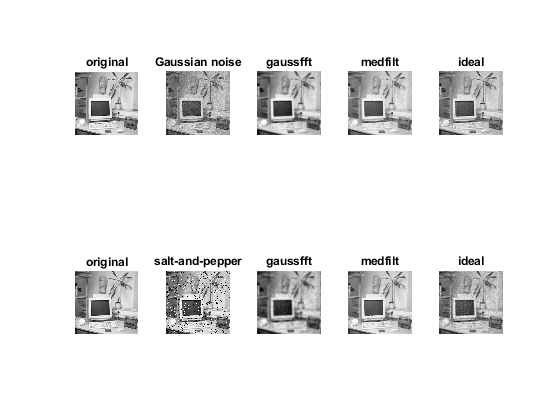

%smoothing
office = office256;
figure(24);

t =3; %gaussian
boxcar = 5; %med
cutoff = 0.20; %ideal

subplot(2, 5, 1);
showgrey(office)
title('original')
add = gaussnoise(office, 16); 
subplot(2, 5, 2);
showgrey(add)
title('Gaussian noise')
gaus1 = gaussfft(add, t); 
subplot(2, 5, 3);
showgrey(gaus1)
title('gaussfft')
med1 = medfilt(add, boxcar); 
subplot(2, 5, 4);
showgrey(med1)
title('medfilt')
ide1 = ideal(add, cutoff, 'l');
subplot(2, 5, 5);
showgrey(ide1)
title('ideal')

t =6; % gaussian
boxcar = 3; % med
cutoff = 0.125; % ideal

subplot(2, 5, 6);
showgrey(office)
title('original')
sap = sapnoise(office, 0.1, 255); 
subplot(2, 5, 7);
showgrey(sap)
title('salt-and-pepper')
gaus2 = gaussfft(sap, t); 
subplot(2, 5, 8);
showgrey(gaus2)
title('gaussfft')
med2 = medfilt(sap, boxcar); 
subplot(2, 5, 9);
showgrey(med2)
title('medfilt')
ide2 = ideal(sap, cutoff, 'l'); 
subplot(2, 5, 10);
showgrey(ide2)
title('ideal')

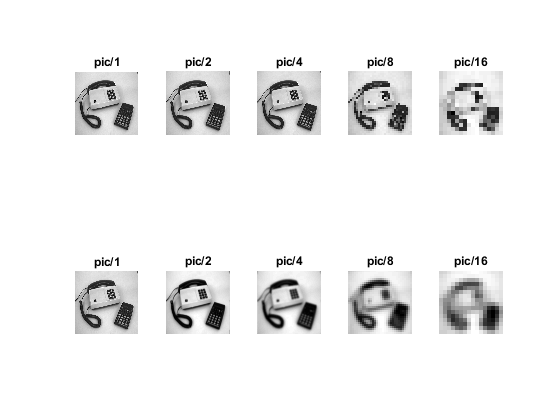

%subsampling
img = phonecalc256;
figure(25);
smoo = img;
fac =1 ;
n=5;
t=2;
for i=1:n
    if i>1 
        smoo = gaussfft(img, t);
        img = rawsubsample(img); 
        smoo = rawsubsample(smoo);
    end
    subplot(2, n, i)
    showgrey(img)
    title(['pic/' num2str(fac)])
    subplot(2, n, i+n)
    showgrey(smoo)
    title(['pic/' num2str(fac)])
    fac = fac * 2;
end

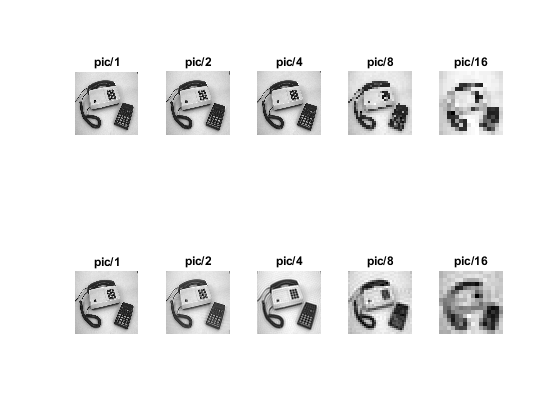

img = phonecalc256;
figure(26);
smoo = img;
fac=1 ;
n=5;
cutoff = 0.25;
for i=1:n
    if i>1 
        smoo = ideal(img, cutoff, 'l'); 
        img = rawsubsample(img); 
        smoo = rawsubsample(smoo);
    end
    subplot(2, n, i)
    showgrey(img)
    title(['pic/' num2str(fac)])
    subplot(2, n, i+n)
    showgrey(smoo)
    title(['pic/' num2str(fac)])
    fac = fac * 2;
end